# DSZOB, cvičenie 8.

## **Zadanie:**

## **Úloha 1 Lineárna filtrácia obrazu v priestorovej doméne**

Vykonajte filtráciu obrazu v priestorovej doméne s využitím konvolúcie. Použite nasledovné filtre:

- Gaussov filter

- Sobelov filter

- Laplacov filter

Postupujte nasledovne:

1. Načítajte si ľubovolný obrázok (imread).

2. Preveďte si obrázok na grayscale (rgb2gray).

    a. Dobrovolné: Môžete robiť aj s farebným rgb obrázkom (3 kanály).

3. Vytvorte si maticu filtra pre konvolúciu (pomôcka: fspecial).

4. Vykonajte konvolúciu (conv2).

V úlohe vizualizujte pôvodný obrázok a výstupy po filtrácii.

**Posudte ci pouzite filtracne jadra pri konvolucii su LP alebo HP! Zdôvodnite !**

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

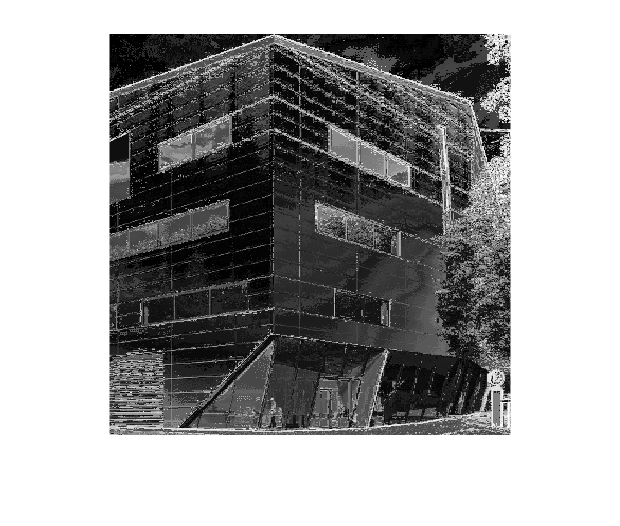

img = imread('img1.png');
imshow(img)

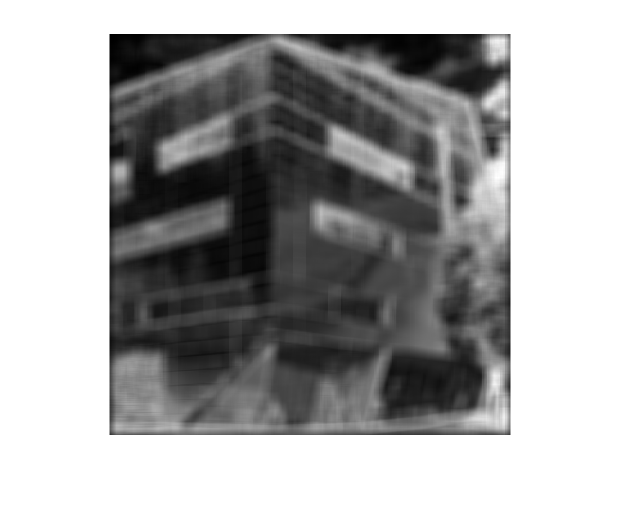

kernell_g = fspecial('gaussian', 13, 15);
%kernell_g = kernell_g ./ sum(kernell_g);0
%kernell_g = kernell_g ./ max(kernell_g(:));
%imshow(uint8(conv2(img, kernell_g, 'same')))
imshow(conv2(img, kernell_g, 'same'), [])

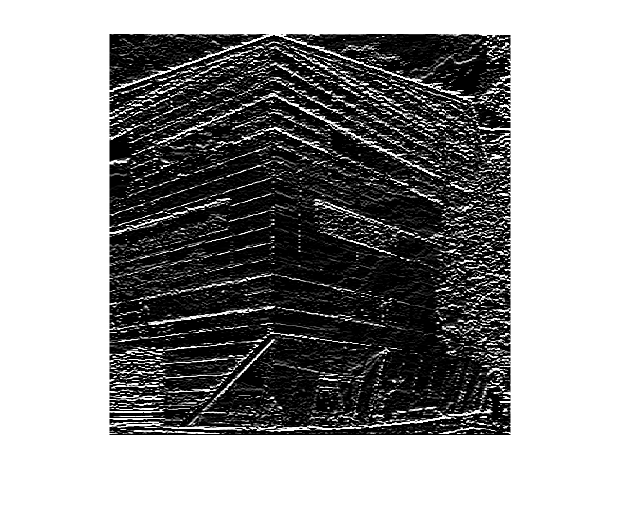

kernell_s = fspecial('sobel');

imshow(uint8(conv2(img, kernell_s, 'same')))

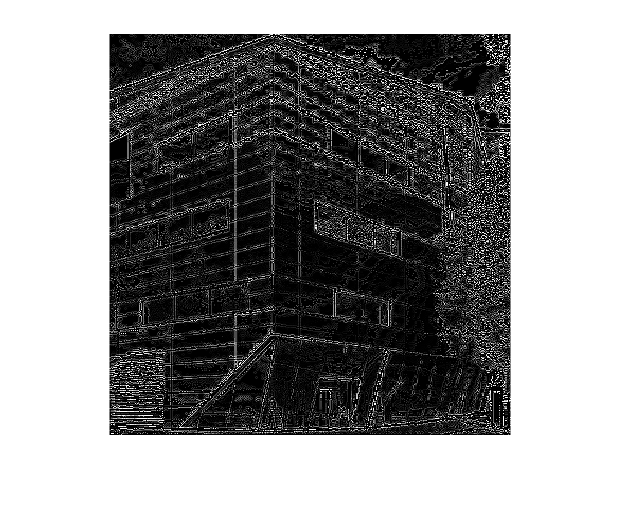

kernell_l = fspecial('laplacian');

imshow(uint8(conv2(img, kernell_l, 'same')))

Pri obrázkoch sa v skratke low pass filtre prejavia rozmazaním obrázku a high pass filtre zvýraznením hrán. Z toho vyplýva:

- Gaussian filter - Low Pass

- Sobel filter - High Pass

- Laplacian filter - High Pass

## **Úloha 2 F**iltrácia obrazu v spektrálnej doméne

Vykonajte nasledovné filtrácie obrazu v spektrálnej doméne:

• Ideálny HP filter

• Ideálny LP filter

• Gaussov HP filter

• Gaussov LP filter

Postupujte nasledovne:

1. Načítajte si obrázok a preveďte ho na grayscale (dobrovoľné: RGB).

2. Vypočítajte Fourierovu transformáciu nad obrázkom (fft2).

3. Správne si posuňte spektrum (prehodenie kvadrantov) (fftshift).

4. Vytvorte si ideálny filter (pomôcka: definícia funkcie pre kruh s využitím polomeru a stredového bodu).

5. Vykonajte filtráciu. (násobenie)

6. Inverzne posuňte spektrum (ifftshift).

7. Vykonajte spätnú transformáciu (ifft2) a vizualizujte obrázok.

Rovnako postupujte aj pri ostatných filtroch. Pri vytvaraní Gaussovho filtra cez fspecial si správne naškálujte filter (pozn. min = 0, max = 1). Vizualizujte aj jednotlivé filtre, ktoré ste vytvorili v tejto úlohe. **Porovnajte a zhodnoďte vplyv jednotlivých filtrov na výsledné vizualizácie.**

img = imread('img1.png');
imshow(img)

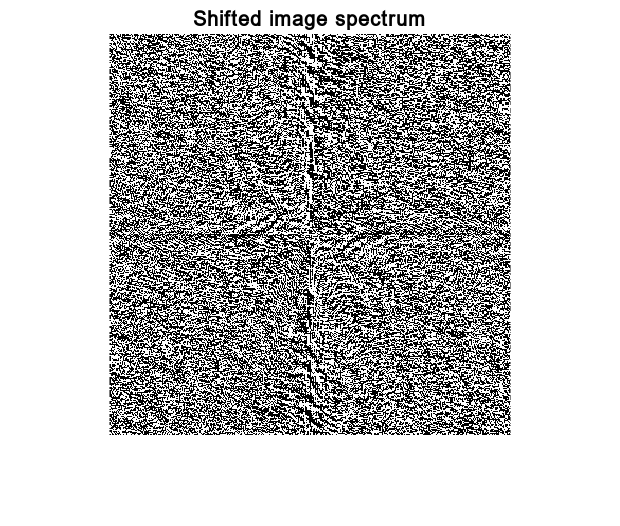

figure();
spectrum = fftshift(fft2(img));
imshow(real(spectrum))
title('Shifted image spectrum')

## Ideálny Low Pass filter:

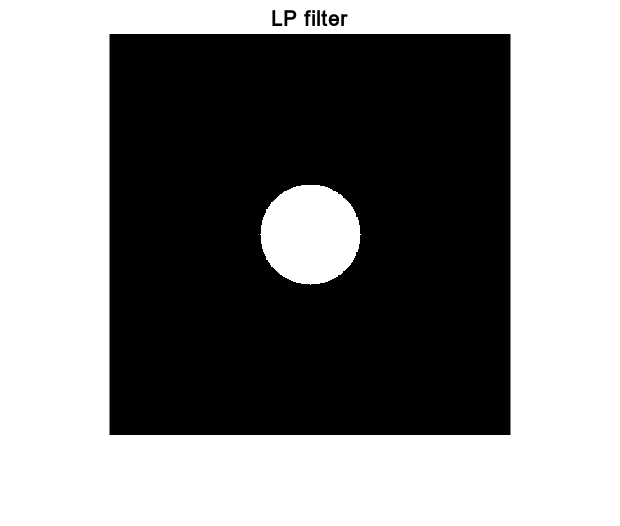

figure();
filter = filter_matrix(width(spectrum), height(spectrum), 50, 'LP');
imshow(filter)
title('LP filter')

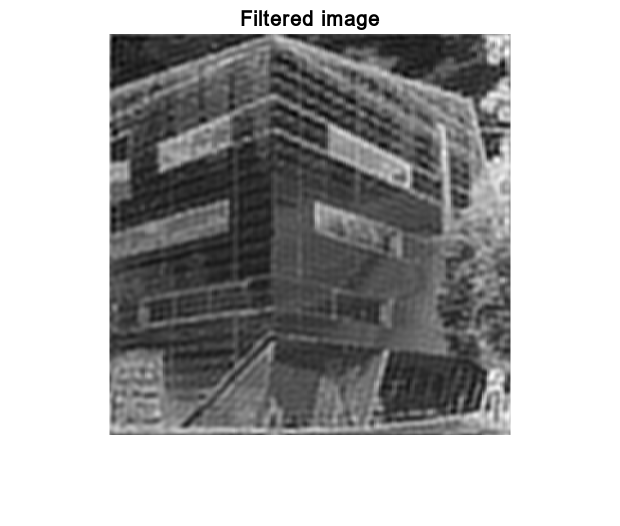

figure();
imshow(ifft2(ifftshift(spectrum .* filter)),[])
title('Filtered image')

## Ideálny High Pass filter:

figure();
filter = filter_matrix(width(spectrum), height(spectrum), 20, 'HP');
imshow(filter)
title('HP filter')

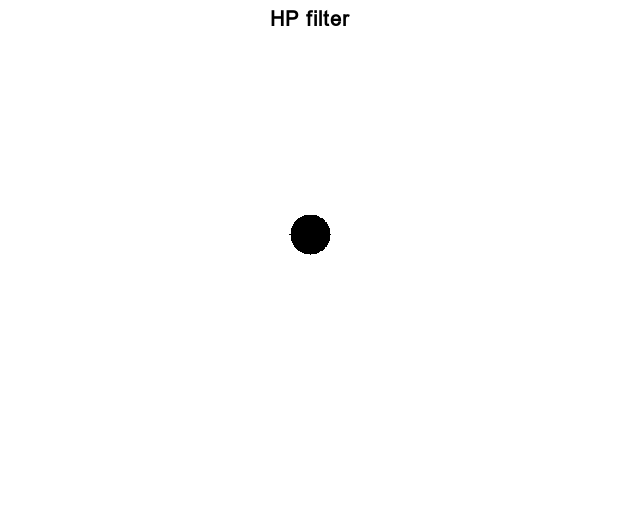

figure();
imshow(ifft2(ifftshift(spectrum .* filter)),[])

title('Filtered image')

## Gaussov Low Pass filter:

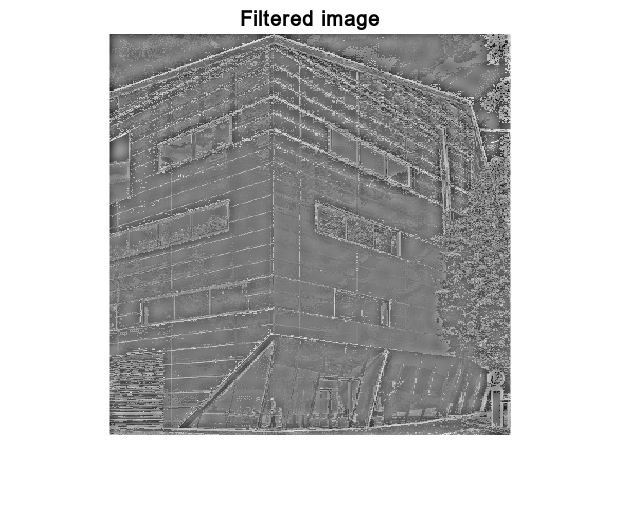

figure();
filter = fspecial('gaussian', 401, 50);
filter = filter ./ max(filter(:));

imshow(filter,[])
title('Gaussian LP filter')

figure();
spectrum = fftshift(fft2(img));
imshow(ifft2(ifftshift(spectrum .* filter)),[])
title('Filtered image')

## Gausso High Pass fiter:

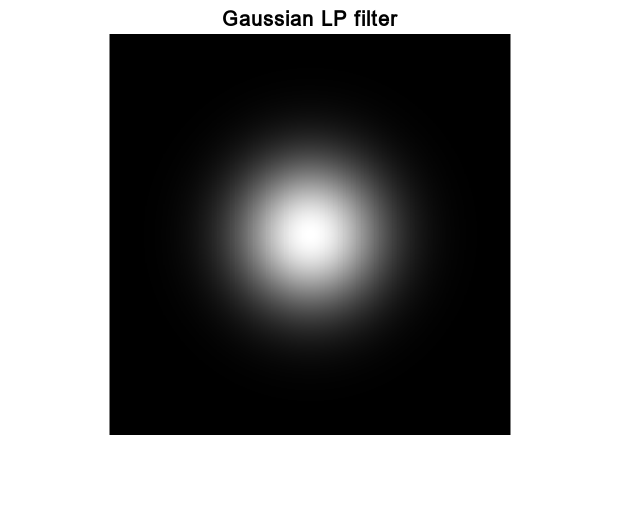

figure();

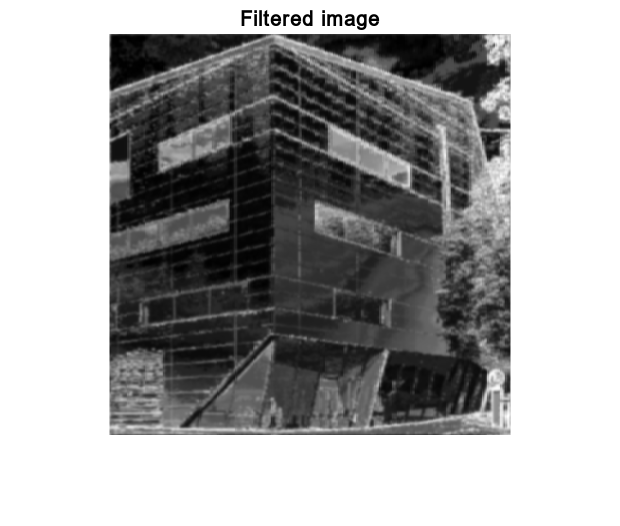

filter = fspecial('gaussian', 401, 20);
filter = filter ./ max(filter(:));
filter = arrayfun(@(x) 1-x,filter);
imshow(filter,[])
title('Gaussian HP filter')

figure();
spectrum = fftshift(fft2(img));
imshow(ifft2(ifftshift(spectrum .* filter)),[])
title('Filtered image')

Rozdiel medzi ideálnymi a gaussovskými filtrami (či už HP alebo LP) je, že prechod od koeficientu 1 po koeficient 0 je pri gaussovskom filtri plynulejší. Navyše, keďže ideálny filter je prakticky rectangular pulse, pozorujeme po inverznej transformácii tzv. ringing effect spôsobený tým, že inverznou fourierovou transformáciou pravouhlého pulzu dostaneme funkciu sinc. Preto sa prakticky častejšie uplatňuje filtrácia gaussovou funkciou.

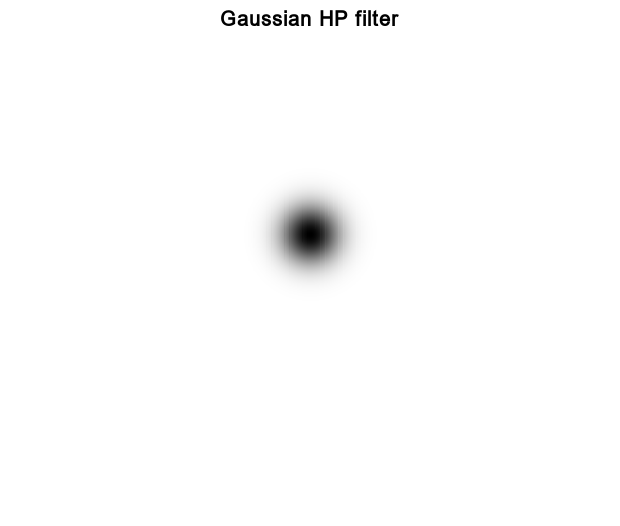

function matrix = filter_matrix(width, height, r, kind)
    x0 = int64(width/2);

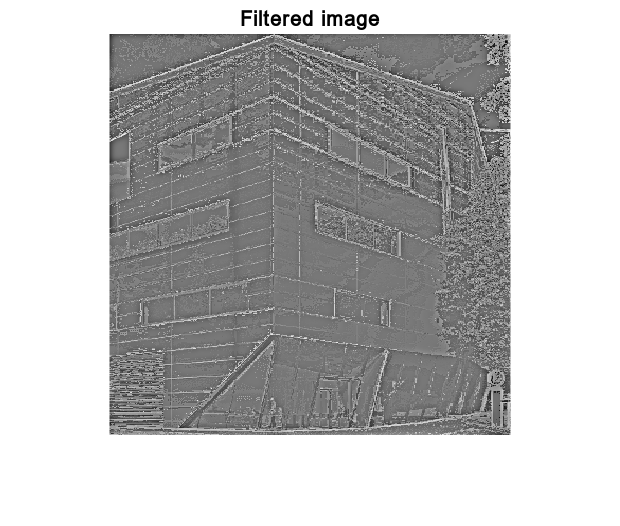

    y0 = int64(height/2);
    matrix = ones(height,width) .* strcmp(kind, 'HP');
    
    for x = 1:1:width
        for y = 1:1:height

            if ((x-x0)^2 + (y-y0)^2 <= r^2)
                matrix(y,x) = 1 * strcmp(kind, 'LP');
            end
        end
    end
end
